[xData, yData] = prepareCurveData( nu, Y );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

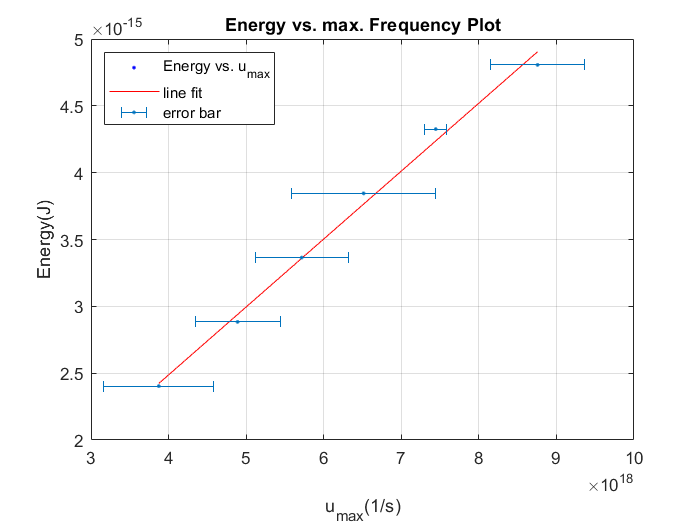


% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'Y vs. nu', 'untitled fit 1', 'Location', 'NorthEast' );

grid on

title('Energy vs. max. Frequency Plot')
xlabel(['' newline 'u_{max}(1/s)'])
ylabel('Energy(J)')
hold on
err=1e+18.*[0.708 0.547 0.598 0.93 0.140 0.609];
errorbar(nu,Y,err, 'horizontal', '.')

legend({'Energy vs. u_{max}','line fit','error bar'},'Location','northwest')


%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =   5.082e-34  (4.5e-34, 5.665e-34)      \pm 0.291e-34
  %     p2 =   4.542e-16  (8.101e-17, 8.273e-16)    \pm 1.866e-16
  
%Goodness of fit:
 % SSE: 2.738e-32
 % R-square: 0.9932
  %Adjusted R-square: 0.9915
 % RMSE: 8.274e-17